# Demarce Williams

## 2-Link Manipulator with Joints and Sliders

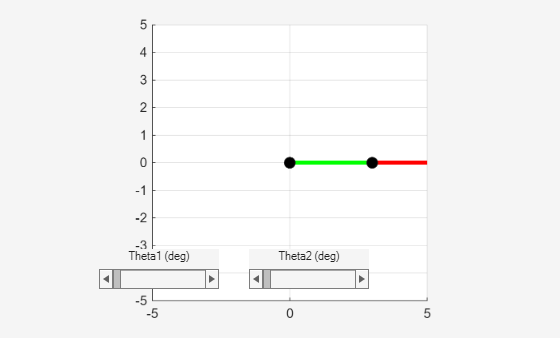


clc; clear; close all;

f1 = figure('Name','Manipulator with Sliders','NumberTitle','off');
axis equal; grid on;
xlim([-7 7]); ylim([-7 7]);
hold on;

% Circle parameters (for joints)
r = 0.2; 
N = 200; 
t = linspace(0,2*pi,N);

% Links
L1 = 3; 
L2 = 3;

% Initial plots (placeholders)
Link1 = plot([0 L1],[0 0],'g-','LineWidth',3);
Link2 = plot([L1 L1+L2],[0 0],'r-','LineWidth',3);

Joint1 = patch(r*cos(t), r*sin(t), 'k'); % base joint at (0,0)
Joint2 = patch(L1+r*cos(t), r*sin(t), 'k'); % second joint
EndEff = patch((L1+L2)+r*cos(t), r*sin(t), 'b'); % end effector joint

% Sliders
theta1Slider = uicontrol('Style','slider','Min',0,'Max',360,'Value',0,...
    'Position',[100 50 120 20],'Callback',@updateArm);
uicontrol('Style','text','Position',[100 70 120 20],'String','Theta1 (deg)');

theta2Slider = uicontrol('Style','slider','Min',0,'Max',360,'Value',0,...
    'Position',[250 50 120 20],'Callback',@updateArm);
uicontrol('Style','text','Position',[250 70 120 20],'String','Theta2 (deg)');


% Store handles
data.L1 = L1; 
data.L2 = L2;
data.r = r; 
data.t = t;
data.Link1 = Link1; 
data.Link2 = Link2;
data.Joint1 = Joint1;
data.Joint2 = Joint2; 
data.EndEff = EndEff;
data.theta1Slider = theta1Slider; 
data.theta2Slider = theta2Slider;

guidata(f1,data);

function updateArm(src,~)
    data = guidata(src);
    th1 = deg2rad(get(data.theta1Slider,'Value'));
    th2 = deg2rad(get(data.theta2Slider,'Value'));

    % Joint positions
    x1 = data.L1*cos(th1); 
    y1 = data.L1*sin(th1);

    x2 = x1 + data.L2*cos(th1+th2);
    y2 = y1 + data.L2*sin(th1+th2);

    % Update links
    set(data.Link1,'XData',[0 x1],'YData',[0 y1]);
    set(data.Link2,'XData',[x1 x2],'YData',[y1 y2]);

    % Update joints
    set(data.Joint1,'XData',data.r*cos(data.t),'YData',data.r*sin(data.t));
    set(data.Joint2,'XData',x1+data.r*cos(data.t),'YData',y1+data.r*sin(data.t));
    set(data.EndEff,'XData',x2+data.r*cos(data.t),'YData',y2+data.r*sin(data.t));

    % Show end effector coordinates
    title(sprintf('End Effector: (%.2f , %.2f)',x2,y2));
end

## 2-Link Manipulator AVI Animation

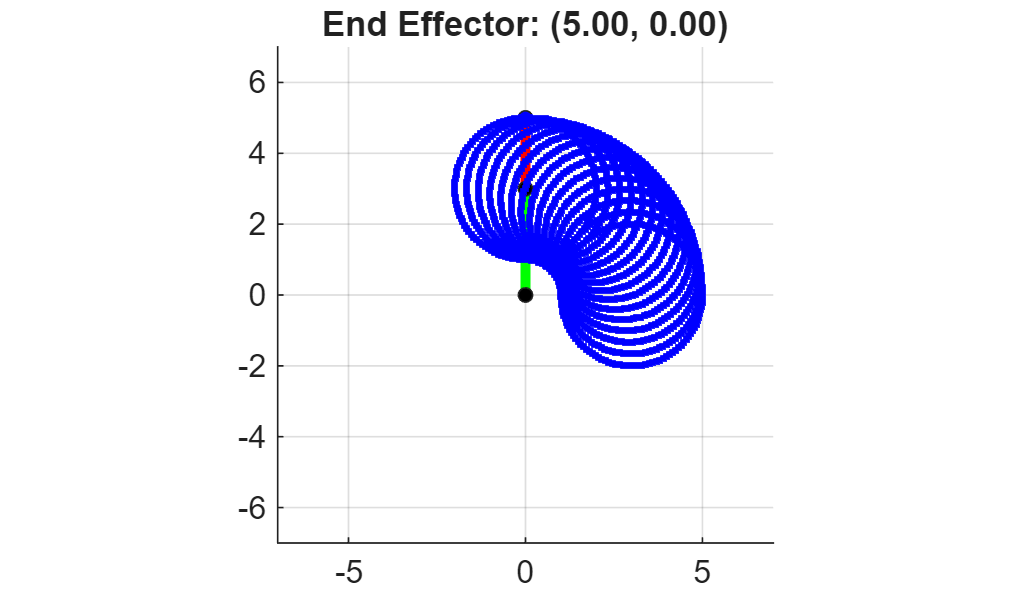

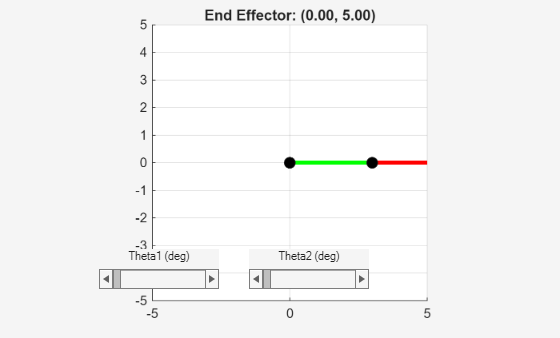

% Create figure (fixed size)
f2 = figure('Name','2-Link Multiple Circles','NumberTitle','off');
set(f2, 'Position', [100 100 700 420]);  % fixed width & height
axis equal; grid on;
xlim([-7 7]); ylim([-7 7]);
hold on;

% Circle for joints
r = 0.2;
N = 200;
t = linspace(0, 2*pi, N);

% Link lengths
L1 = 3;
L2 = 2;

% Initial drawings
Link1 = plot([0 L1], [0 0], 'g-', 'LineWidth', 3);
Link2 = plot([L1 L1+L2], [0 0], 'r-', 'LineWidth', 3);
Joint1 = patch(r*cos(t), r*sin(t), 'k'); % base
Joint2 = patch(L1 + r*cos(t), r*sin(t), 'k'); % joint
EndEff  = patch((L1+L2) + r*cos(t), r*sin(t), 'b'); % end effector
Endeff_traj = plot(NaN, NaN, 'b.');  % trajectory

% Rotation values
theta1 = linspace(0, pi/2, 15);   % Link1 positions (6 circles total)
theta2 = linspace(0, 2*pi, 120); % Link2 resolution per circle

% Video setup
totalFrames = length(theta1) * length(theta2);
fps = totalFrames / 120; % adjust so video ≈ 60 sec
v = VideoWriter('enddeff_animation.avi');
v.FrameRate = fps;
open(v);

% Trajectory storage
trajX = [];
trajY = [];

for i = 1:length(theta1)
    th1 = theta1(i);

    % Link1 endpoint
    x1 = L1*cos(th1);
    y1 = L1*sin(th1);

    for j = 1:length(theta2)
        th2 = theta2(j);

        % End effector position
        x2 = x1 + L2*cos(th1 + th2);
        y2 = y1 + L2*sin(th1 + th2);

        % Update graphics
        set(Link1, 'XData', [0 x1], 'YData', [0 y1]);
        set(Link2, 'XData', [x1 x2], 'YData', [y1 y2]);
        set(Joint1, 'XData', r*cos(t), 'YData', r*sin(t));
        set(Joint2, 'XData', x1 + r*cos(t), 'YData', y1 + r*sin(t));
        set(EndEff, 'XData', x2 + r*cos(t), 'YData', y2 + r*sin(t));

        % Update trajectory
        trajX(end+1) = x2;
        trajY(end+1) = y2;
        set(Endeff_traj, 'XData', trajX, 'YData', trajY);

        % Update title
        title(sprintf('End Effector: (%.2f, %.2f)', x2, y2));

        % Capture frame
        imgFile = sprintf('frame_%04d.png', i*length(theta2)+j);
        exportgraphics(f2, imgFile, 'Resolution',150);
        frame = imread(imgFile);
        writeVideo(v, frame);
    end
end


close(v);
disp('Video saved as enddeff_animation.avi');

Video saved as enddeff_animation.avi
